# Performance evaluation: ROC curves

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared two trained classifiers with you and some previously unseen testing data:

clear all;
load('classifiers.mat', 'm_nb', 'm_dt', 'test_examples', 'test_labels');

Your task is to analyse the True Positive Rate (TPR) and False Positive Rate (FPR) for each classifier in order to make a decision about which one is performing best.

Marks are available for:

- Using each classifier to predict labels and associated likelihood scores for the test data [4 marks]

- Computing the TPR for each classifier, taking "malignant" as the positive class [3 marks]

- Computing the FPR for each classifier, taking "malignant" as the positive class [3 marks]

- Generating a Receiver Operating Characteristic (ROC) curve for each classifier and plotting them together on a single graph with a legend and labelled axes [4 marks]

- Deciding on the best classifier based on a sensible quantitative comparison between the ROC curves [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:
summary(test_examples)


Variables:

    id: 142×1 double

        Values:

            Min            86208
            Median    9.0494e+05
            Max        9.113e+08

    radius_mean: 142×1 double

        Values:

            Min           7.729    
            Median       13.655    
            Max           28.11    

    texture_mean: 142×1 double

        Values:

            Min             9.71    
            Median        19.085    
            Max            32.47    

    perimeter_mean: 142×1 double

        Values:

            Min            47.98      
            Median         87.97      
            Max            188.5      

    area_mean: 142×1 double

        Values:

            Min          178.8   
            Median      574.25   
            Max           2499   

    smoothness_mean: 142×1 double

        Values:

            Min            0.06251     
            Median


%Decision Tree
predictions = predict(m_dt, test_examples);
%show first 25 predictions
predictions(1:25)

ans = 25×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 


%calculating true predictions
[c,order] = confusionmat(test_labels, predictions)

c =     82     3
     5    52


order = 2×1 categorical array
     Benign 
     Malignant 


%compute the TDR (True Positive Rate)
%TP / (TP + FN)
tpr = 52 / (52 + 5)

tpr = 0.9123

%compute the FPR (False Positive Rate(
%FP / (FP + TN)
fpr = 3 / (3 + 83)

fpr = 0.0349


%Naive Bayes
predictionsNB = predict(m_nb, test_examples);
%show first 25 predictions
predictionsNB(1:25)

ans = 25×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 


%calculating true predictions
[c,order] = confusionmat(test_labels, predictionsNB)

c =     83     2
     4    53


order = 2×1 categorical array
     Benign 
     Malignant 


%compute the TDR (True Positive Rate)
%TP / (TP + FN)
tpr1 = 53 / (53 + 4)

tpr1 = 0.9298

%compute the FPR (False Positive Rate(
%FP / (FP + TN)
fpr1 = 2 / (2 + 82)

fpr1 = 0.0238


m_dt.ClassNames

ans = 2×1 categorical array
     Benign 
     Malignant 


%Generate an ROC curve for Decision Trees 
[prediction, score] = predict(m_dt, test_examples)

prediction = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benig

score =      0     1
     0     1
     1     0
     1     0
     0     1
     0     1
     1     0
     1     0
     0     1
     1     0


[Xd,Yd] = perfcurve(test_labels,score(:,2), 'Malignant')

Xd =          0
    0.0118
    0.0353
    0.0471
    1.0000


Yd =          0
    0.8947
    0.9123
    0.9123
    1.0000


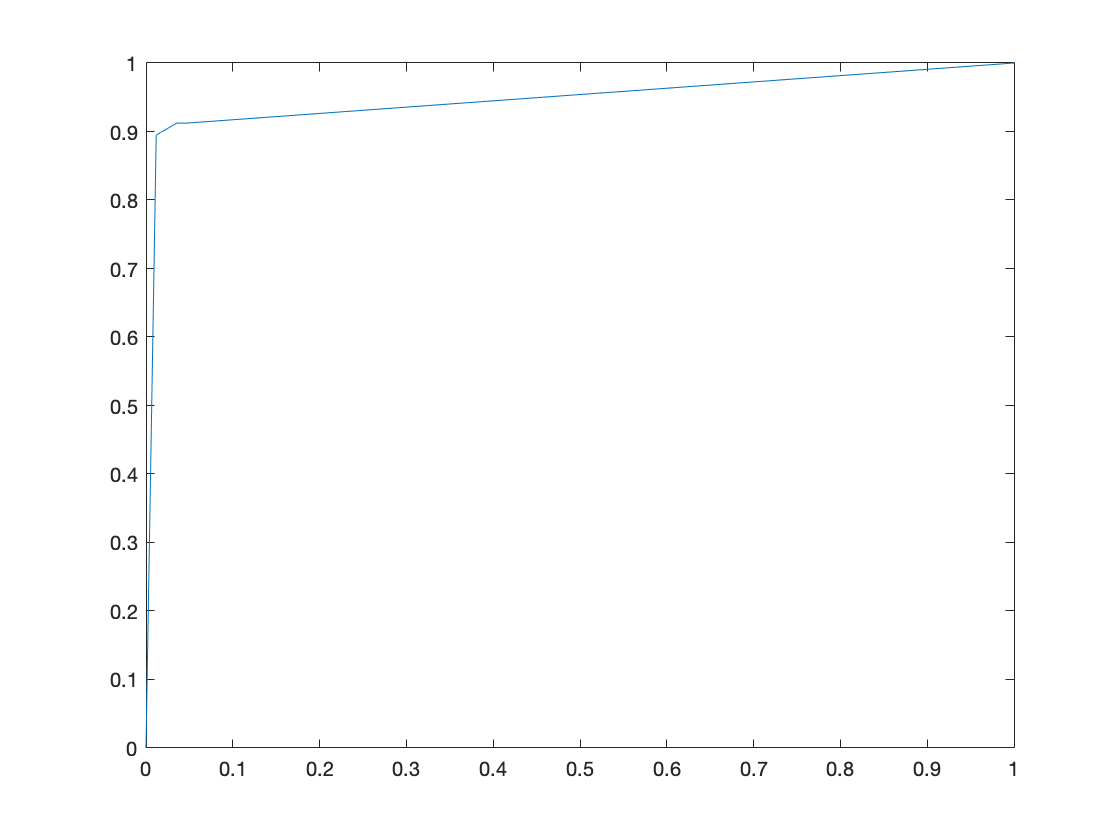

plot(Xd,Yd)


m_nb.ClassNames

ans = 2×1 categorical array
     Benign 
     Malignant 


%Generate an ROC curve for Naive Bayes 
[predictionNB, score] = predict(m_nb, test_examples)

predictionNB = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Ben

score =     0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    1.0000    0.0000


[Xn,Yn] = perfcurve(test_labels,score(:,2), 'Malignant')

Xn =          0
         0
         0
         0
         0
         0
         0
         0
         0
    0.0118


Yn =          0
    0.7895
    0.8070
    0.8246
    0.8421
    0.8596
    0.8772
    0.8947
    0.9123
    0.9123


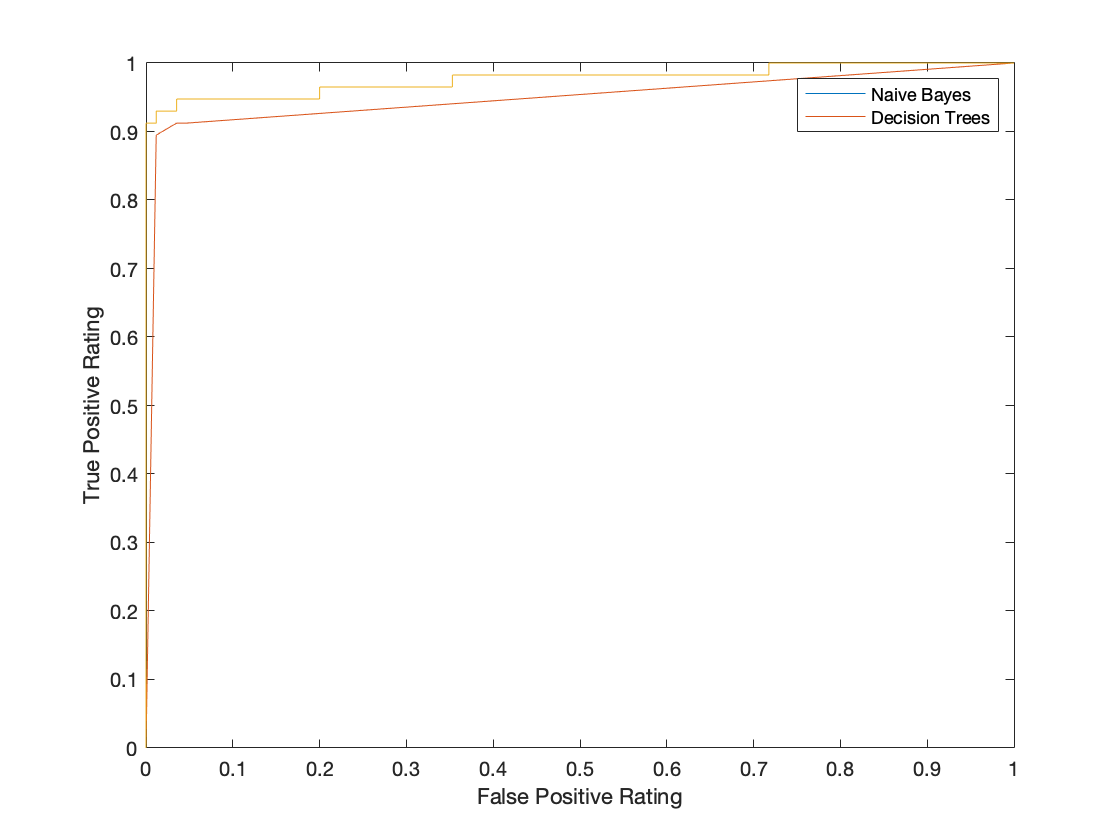

plot(Xn,Yn)

%Plot the curves together in a single graph
hold on 
plot(Xd, Yd)
plot(Xn, Yn)
legend('Naive Bayes', 'Decision Trees')
xlabel('False Positive Rating')
ylabel('True Positive Rating')
hold off


%Decide on the best classifier based on a quantitive comparison AUC = Area under code 
AUCdt = trapz(Xd, Yd)

AUCdt = 0.9484


%NB has the higher score so is rated the better classifer in this problem
AUCnb = trapz(Xn, Yn)

AUCnb = 0.9769